# Lecture 3: Equilibrium Points & Linearization

- Find the kinetic energy fo the system $T$.

- Find the potential energy of the system $V$. 

- Find the equilibrium points $q_{0\;}$.

- Classify the stability of the equilibrium points

- Find the linearized equations of motion about equilibrium

Welcome! A spring mass damper system on an incline is connected to a massless rod with a point mass at the end. Choose the generalized coordinates $q=\left\lbrack \begin{array}{c}
x\;\\
\theta \;\;
\end{array}\right\rbrack$.

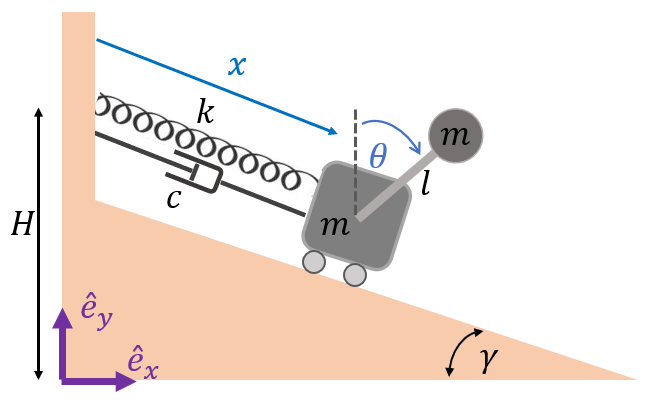

Assume the following properties:

- $l$ = 3                [m]

- $m$ = 5               [kg]

- $g$ = 9.81           [m/$s^{2\;}$]

- $\gamma \;$ = $\pi \;/6$           [rad]

- $H$ = 30              [m]

- $k=5$               [N/m]

- $l_0$ = 0                [m]

- $c=0\ldotp 4$            [Ns/m]

## Kinetic Energy

The kinetic energy of each object is calculated using the formula below. Since there are only point masses in the system $J_G =0$. 


$$T=\frac{1}{2}m{\dot{r_G } }^{T\;} \dot{r_G } +\frac{1}{2}J_G \omega {\;}^2$$



$$T=\frac{1}{2}m{\dot{r_G } }^{T\;} \dot{r_G }$$


clc; clear all; close all;

syms x x_dot x_ddot theta theta_dot theta_ddot
% syms L m g gamma H k c

L = 3;
m = 5;
g = 9.81;
gamma = pi/6;
H = 30;
k = 5;
c = 0.4;

% Generalized Coordinates
q = [x;
    theta];
q_dot = [x_dot;
    theta_dot];
q_ddot = [x_ddot;
    theta_ddot];

% Position vectors
r_1 = [x*cos(gamma);
    H-x*sin(gamma)];
r_2 = [x*cos(gamma)+L*sin(theta);
    H-x*sin(gamma)+L*cos(theta)];

% Velocity vectors
r_dot_1 = jacobian(r_1,q)*q_dot;
r_dot_2 = jacobian(r_2,q)*q_dot;

% Kinetic Energy
T_1 = 1/2*m*transpose(r_dot_1)*r_dot_1;
T_2 = 1/2*m*transpose(r_dot_2)*r_dot_2;
T = T_1 + T_2;
T = simplify(T)

$$T = \frac{45\,{\dot{\theta }}^{2}}{2}+5\,{\dot{x}}^{2}+\frac{15\,\dot{\theta }\,\dot{x}\,\sin\left(\theta \right)}{2}+\frac{15\,\sqrt{3}\,\dot{\theta }\,\dot{x}\,\cos\left(\theta \right)}{2}$$

## Potential Energy

The potential energy for the spring is given by the formula below. Neglect unstretched length ($l_{0\;} =0$).


$$V_k =\frac{1}{2}{k\left(x-l_{0\;} \right)}^{2\;}$$


The gravitational potential energy of each mass is calculated using the formula below. $y$ is the vertical height from the reference frame.


$$V_g =\textrm{mgy}$$


% Elastic Potential Energy
L_0 = 0;
V_k = 0.5*k*(x-L_0)^2;

% Gravitational Potential Energy
V_g_1 = m*g*r_1(2);
V_g_2 = m*g*r_2(2);

% Combined
V = V_k + V_g_1 + V_g_2;
V = simplify(V)

$$V = \frac{5\,x^{2}}{2}-\frac{981\,x}{20}+\frac{2943\,\cos\left(\theta \right)}{20}+2943$$

## Generalized non-conservative force vector

First identify the non conservative forces $F_i$, and moments $M_j$. Then find the absolute position vectors $r_{i\;}$to where the forces are applied and the absolute rotation vectors $\theta_j$ to where the moments are applied. In this case, there the only non conservative forces are from the damper. The damper force against the wall will do no work (the wall isn't moving) so we can neglect it. However, the force due to the damper acting against the mass needs to be accounted for.


$$Q^{\textrm{nc}} =\sum_{i=1}^{n_F } {\left(r_{i,q} \right)}^T F_i +\sum_{j=1}^{n_M } {\left(\theta {\;}_{j,q} \right)}^T M_j$$



$$Q^{\textrm{nc}} ={\left(r_q \right)}^T F_{\;}$$


% Damper force vector
F = c*x_dot; % Magnitude of Damper force
F_vec = [-F*cos(gamma);
    F*sin(gamma);
    0];

% Position vector to where force applied
r_vec = [x*cos(gamma);
    H-x*sin(gamma);
    0];

Q_nc = transpose(jacobian(r_vec,q))*F_vec;
Q_nc = simplify(Q_nc)

$$Q\_nc = \left(\begin{array}{c} -\frac{2\,\dot{x}}{5}\\ 0 \end{array}\right)$$

## Lagrange Equations of Motion

The equations of motion for each of the generalized coordinates can be found from


$$\frac{d}{\textrm{dt}}\left(T,_{\dot{q} } \right)-T,_q +V,_q ={\left(Q^{\textrm{nc}} \right)}^T$$


Note that the first term can be found from the chain rule. 


$$\frac{d}{\textrm{dt}}\left(T,_{\dot{q} } \right)={\left(\frac{\partial {\left(T_{,\dot{q} } \right)}^T }{\partial \;q}\dot{q} +\frac{\partial {\left(T,_{\dot{q} } \right)}^T }{\partial \;\dot{q} }\ddot{q} +\frac{\partial {\left(T,_{\dot{q} } \right)}^T }{\partial \;s}\dot{s} +\frac{\partial {\left(T,_{\dot{q} } \right)}^T }{\partial \;\dot{s} }\ddot{s} \right)}^T$$


But since there are no prescribed displacements ($s=0$) then


$$\frac{d}{\textrm{dt}}\left(T,_{\dot{q} } \right)={\left(\frac{\partial {\left(T_{,\dot{q} } \right)}^T }{\partial \;q}\dot{q} +\frac{\partial {\left(T,_{\dot{q} } \right)}^T }{\partial \;\dot{q} }\ddot{q} \right)}^T$$


% First term
dTdq_dot = jacobian(T,q_dot);
First_Term = jacobian(transpose(dTdq_dot),q)*q_dot + jacobian(transpose(dTdq_dot),q_dot)*q_ddot;
First_Term = transpose(First_Term); 

% Second term
Second_Term = jacobian(T,q);
Second_Term = simplify(Second_Term);

% Third term
Third_Term = jacobian(V,q);
Third_Term = simplify(Third_Term);

% Equation of Motion
EoM = First_Term - Second_Term + Third_Term == transpose(Q_nc);
EoM = simplify(EoM);
EoM = transpose(EoM)

$$EoM = \left(\begin{array}{c} 150\,\cos\left(\theta \right)\,{\dot{\theta }}^{2}+100\,x+8\,\dot{x}+200\,\ddot{x}+150\,\ddot{\theta }\,\sin\left(\theta \right)+150\,\sqrt{3}\,\ddot{\theta }\,\cos\left(\theta \right)=150\,\sqrt{3}\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}+981\\ 981\,\sin\left(\theta \right)=300\,\ddot{\theta }+50\,\ddot{x}\,\sin\left(\theta \right)+50\,\sqrt{3}\,\ddot{x}\,\cos\left(\theta \right) \end{array}\right)$$

## Equilibrium Points

Solve for equilibrium Points by finding the stationary points of the potential energy


$${\left(V_{,q} \right)}^T =0$$


The MATLAB solve() and vpasolve() functions are pretty bad (in my opinion) so I'd usually recommend solving by hand or using Mathematica.

dVdq = transpose(jacobian(V,q));
dVdq = simplify(dVdq)

$$dVdq = \left(\begin{array}{c} 5\,x-\frac{981}{20}\\ -\frac{2943\,\sin\left(\theta \right)}{20} \end{array}\right)$$

[x_0, theta_0] = vpasolve(dVdq(1) == 0, dVdq(2) == 0,[x, theta],[0,pi]); %solve dVdq = 0 with initial guess x=0 & theta=pi
q_0 = [x_0; theta_0];
q_0 = double(q_0)

q_0 =     9.8100
    3.1416


Find if the equilibrium point is stable or not. $q_0$ is stable if the hessian of $V$ is positive definite:


$${\left(V_{,q} \right)}_{,q\;|q=q_{0,} \dot{q} =0}^T \succ 0$$


For simplicity, we'll treat any other result as unstable. There are many ways to show if a matrix is positive definite. One way is to find the eigenvalues of the matrix, and if all the eigenvalues are positive then the matrix is positive definite. 

% Find hessian and sub in equilibrium point
dVdq2 = hessian(V,q);
dVdq2 = simplify(dVdq2);
dVdq2 = subs(dVdq2,q,q_0); % sub in q0

% Determine if positive definite
eig_val = eig(dVdq2);
isposdef = all(eig_val > 0) % if =1 then stable.

isposdef = logical
   1


## Linearization

We've found that one stable equilibrium point is $q_0 =\left\lbrack \begin{array}{c}
\frac{2\textrm{mg}}{k}\sin \left(\gamma \right)\\
\pi \;
\end{array}\right\rbrack$. We can approximate the equations of motion near this equilibrium point using the substitution: 


$${q\left(t\right)=q_0 +q}_1 \left(t\right)$$



$${\dot{q} \left(t\right)=\dot{q} }_1 \left(t\right)$$



$${\ddot{q} \left(t\right)=\ddot{q} }_1 \left(t\right)$$


Where the term $q_1$ is a *small* displacement from the equilibrium. The approximate linear Equation of Motion near this fixed point can be found using this formula:


$$M_0 \ddot{q_1 } +D_0 \dot{q_1 } +\left(K_0 +K_0^Q \right)q_1 =Q\left(t\right)$$


Mass Matrix:                                             $M_0 ={\left(T_{,\dot{q} } \right)}_{,\dot{q} \;|q=q_{0,} \dot{q} =0}^T$

Damping Matrix:                                       $D_0 =-{Q^{\textrm{nc}} }_{,\dot{q} \;|q=q_{0,} \dot{q} =0}$

Stiffness Matrix:                                       $K_0 ={\left(V_{,q} \right)}_{,q\;|q=q_{0,} \dot{q} =0}^T$

Non Conservative Stiffness Matrix:         $K_0^Q =-{Q^{\textrm{nc}} }_{,q|q=q_{0,} \dot{q} =0}$

Force Vector:                                           $Q\left(t\right)={Q^{\textrm{nc}} }_{|q=q_{0,} \dot{q} =0}$

M_0 = hessian(T,q_dot);
M_0 = subs(M_0,q,q_0); %sub in q = q_0
M_0 = subs(M_0,q_dot,[0;0]) % sub in q_dot = 0

$$M\_0 = \left(\begin{array}{cc} 10 & -\frac{15\,\sqrt{3}}{2}\\ -\frac{15\,\sqrt{3}}{2} & 45 \end{array}\right)$$


D_0 = jacobian(-Q_nc,q_dot);
D_0 = subs(D_0,q,q_0);
D_0 = subs(D_0,q_dot,[0;0])

$$D\_0 = \left(\begin{array}{cc} \frac{2}{5} & 0\\ 0 & 0 \end{array}\right)$$


K_0 = hessian(V,q);
K_0 = subs(K_0,q,q_0);
K_0 = subs(K_0,q_dot,[0;0])

$$K\_0 = \left(\begin{array}{cc} 5 & 0\\ 0 & \frac{2943}{20} \end{array}\right)$$


K_0_Q = jacobian(-Q_nc,q);
K_0_Q = subs(K_0_Q,q,q_0);
K_0_Q = subs(K_0_Q,q_dot,[0;0])

$$K\_0\_Q = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$


Q = subs(Q_nc,q,q_0);
Q = subs(Q,q_dot,[0;0])

$$Q = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$


EoM_linearized = M_0*q_ddot + D_0*q_dot + (K_0+K_0_Q)*(q-q_0) == Q

$$EoM\_linearized = \left(\begin{array}{c} 5\,x+\frac{2\,\dot{x}}{5}+10\,\ddot{x}-\frac{15\,\sqrt{3}\,\ddot{\theta }}{2}-\frac{981}{20}=0\\ \frac{2943\,\theta }{20}+45\,\ddot{\theta }-\frac{2943\,\pi }{20}-\frac{15\,\sqrt{3}\,\ddot{x}}{2}=0 \end{array}\right)$$

## Simulation

*(don't worry if you don't understand the code below. A separate video & example will be provided showing you how to implement this easily in Simulink)*

One way to solve this is to put the equation of motion in state space form (beyond scope of this course) & to simulate it using ODE45.

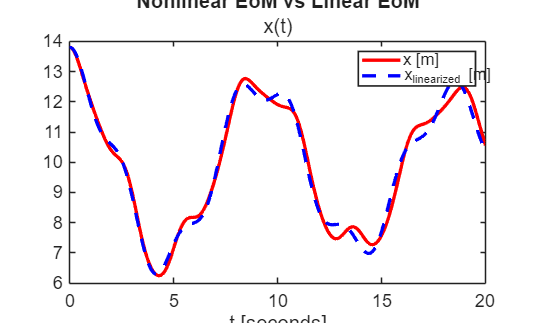

syms x(t) theta(t)
t_interval = [0,20];
y_IC = [q_0(1)+4, 0, q_0(2)+0.3, 0]; % Initial position & Initial velocity (in state space form)
    % y1 = x
    % y2 = d/dt x
    % y3 = theta
    % y4 = d/dt theta
S_desired = ["x"; "Dx"; "theta"; "Dtheta"]; % elements of state

%% Nonlinear EoM simulation calcs
EoM = subs(EoM, {'x', 'theta', 'x_dot', 'theta_dot', 'x_ddot', 'theta_ddot'}, [x(t) theta(t), diff(x,t), diff(theta,t), diff(x,t,2), diff(theta,t,2)]);
EoM = formula(EoM);
[F, S] = odeToVectorField(EoM(1),EoM(2));
S = string(S);
for i = 1:length(S_desired)
    index(i) = find(S == S_desired(i));
end
V_fun = matlabFunction(F,'vars',{'t','Y'});
y_IC = y_IC(index);
[t_sol,y_sol] = ode45(V_fun,t_interval,y_IC);
y_sol = y_sol(:,index);
x_sol = y_sol(:,1);
theta_sol = y_sol(:,3);

%% Linear EoM Simulations calcs
EoM_linearized = subs(EoM_linearized, {'x', 'theta', 'x_dot', 'theta_dot', 'x_ddot', 'theta_ddot'}, [x(t) theta(t), diff(x,t), diff(theta,t), diff(x,t,2), diff(theta,t,2)]);
EoM_linearized = formula(EoM_linearized);
[F, S] = odeToVectorField(EoM_linearized(1),EoM_linearized(2));
S = string(S);
for i = 1:length(S_desired)
    index(i) = find(S == S_desired(i));
end
V_fun = matlabFunction(F,'vars',{'t','Y'});
[t_linear_sol,y_sol] = ode45(V_fun,t_interval,y_IC);
y_sol = y_sol(:,index);
x_linear_sol = y_sol(:,1);
theta_linear_sol = y_sol(:,3);

% Plot
plot(t_sol,x_sol,'r','LineWidth',2,'DisplayName','x [m]')
hold on
plot(t_linear_sol,x_linear_sol,'b--','LineWidth',2,'DisplayName','x_{linearized} [m]')
hold off
xlabel('t [seconds]')
legend()
title('Nonlinear EoM vs Linear EoM')
subtitle('x(t)')

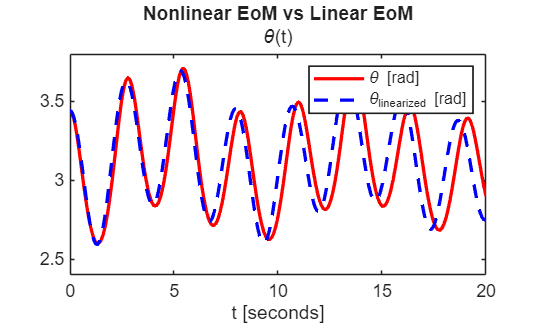


plot(t_sol,theta_sol,'r','LineWidth',2,'DisplayName','\theta [rad]')
hold on
plot(t_linear_sol,theta_linear_sol,'b--','LineWidth',2,'DisplayName','\theta_{linearized} [rad]')
xlabel('t [seconds]')
title('Nonlinear EoM vs Linear EoM')
subtitle('\theta(t)')
legend()